# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Explore and Organize Image Dataset 

Your goal in this step is to define defect classes and labels (keep it small).

- Load and inspect the images and labels from your chosen dataset (see the project page on GitHub for recommended datasets) to understand the part types, defect classes, and data balance

- Store labels in a table loaded by `readtable(...)`

- Manage images and labels with `imageDatastore(...)` and the `Labels` property (or use the example workflow for setting up labeled image datastores).

- Helpful reference: [Create and Explore Datastore for Image Classification](https://www.mathworks.com/help/deeplearning/ug/create-and-explore-datastore-for-image-classification.html).

- Choose 2-3 defect types (for FAIL) plus PASS

%The following creates a table, where the code can be reused to separate
% labels in other data sets that follow the same structure (part type
% pass/fail, along with the defect types in the fail folder)

%THIS TASK MUST BE RAN IN ORDER TO GET THE REST OF THE SYSTEM TO RUN
% Otherwise, no other task will run

%Insert your directory here (the place in your computer where the dataset
%is stored) and then click "Run Section" in the toolbar under "SECTION" above to run Task 1

%(change your file type to "All Files (*.*)" when searching for any images)
rawData = "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5";

imds = imageDatastore(rawData, IncludeSubfolders=true);

%Store text of file names in array
files = string(imds.Files);
elem = numel(files);

parts = strings(elem, 1);
condition = strings(elem, 1);
defectType = strings(elem, 1);


for k = 1:elem
    %Goes through the directory each time and splits objects based on
    %filename
    folderNames = split(files(k), filesep);

    idx = length(folderNames);
    
    %Assigns label to each image based on folder type
    if folderNames(idx-1) == "PASS"
        parts(k) = folderNames(idx-2);
        condition(k) = "PASS";
        defectType(k) = "NONE";
    else
        parts(k) = folderNames(idx-3);
        condition(k) = "FAIL";
        defectType(k) = folderNames(idx-1);
    end
end

disp("The table of the entire dataset separated by part, pass/fail, and defect type")

The table of the entire dataset separated by part, pass/fail, and defect type


dataSetTable = table(files, categorical(parts), categorical(condition),...
 categorical(defectType), 'VariableNames', {'Filename', 'Part', 'Part Condition', 'Defect Type'});

disp(dataSetTable)

                                             Filename                                                Part      Part Condition        Defect Type    
    ___________________________________________________________________________________________    ________    ______________    ___________________

    "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\bottle\FAIL\broken_large\000.png"         bottle           FAIL         broken_large       
    "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\bottle\FAIL\broken_large\001.png"         bottle           FAIL         broken_large       
    "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\bottle\FAIL\broken_large\002.png"         bottle           FAIL         broken_large       
    "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\bottle\FAIL\broken_large\003.png"         bottle           FA

## Task 2: Build a Single-Image Inspection Function

Your goal in this step is to create a function that analyzes and image to identify and quantify suspected defects detected in the image. You're trying to answer the question: "What in the image looks suspicious?"

To build this function you will need to:

**STEP 1. Standardize the images**

- Read images with `imread(...)` or through `imageDatastore(...)`.

- Standardize size with `imresize(...)` so metrics and model input are consistent.

- Convert to grayscale with `rgb2gray(...)` as needed (e.g. classical processing may rely on intensity values)

**STEP 2. Preprocess the images**

- Apply classical preprocessing, prioritizing stability over complexity. In other words, apply only what you need to reduce sensitivity to normal station variation. Suggested processing includes:

- Lighting correction: `imflatfield(...)` (or background estimate with `imgaussfilt(...)` and subtraction)

- Contrast normalization: `adapthisteq(...)`

- Denoising: `medfilt2(...)` or `imgaussfilt(...)`

- Save intermediate results during development (e.g., `imshowpair(...)`) for quick debugging.

**STEP 3. *****Optionally*****, define a region of interest (ROI)**

If each image already contains a centered part with minimal clutter, skip ROI and use the full image:

- `roi = I;`

If needed, define ROI fully automatically (no per-image manual selection), by using, for example:

- Fixed crop defined once (camera is consistent): indexing or `imcrop(...) `OR

- Auto-crop from the part mask: segment the part, compute `BoundingBox` using `regionprops(...)`, then `imcrop(...)`.

**STEP 4. Segment the image for an evidence overlay**

Your goal is to generate an evidence overlay and a few measurable numbers—not a perfect segmentation. Generate a simple binary mask that highlights suspicious regions in the image. Use a defect-appropriate recipe and keep it short:

- Start with thresholding: `imbinarize(...)` or `adaptthresh(...)` + `imbinarize(...)`

- Clean small specks: `bwareaopen(...)`

- Bridge gaps (if appropriate): `imclose(...)`

- Fill holes (only when it matches your goal (e.g., for a clean outer part silhouette): `imfill(...,'holes')`

Deliverable: `maskEvidence = defectEvidence(roi)`

**STEP 5. Extract a small set of interpretable metrics**

Your goal is to quantify the evidence for suspected defects, which supports traceability and debugging in your workflow. These metrics should answer the question: “What did the algorithm see, and how strong was the evidence?”

These measurements are mainly for traceability (inspection logs), debugging, and sanity checks. Keep it to 3–4 metrics so it stays easy.

Recommended minimal metrics (works for many defect types):

- `numComponents`: how many separate suspicious regions were found (use `bwconncomp(maskEvidence)` and read `NumObjects`)

- `maxArea`: size of the largest suspicious region (use `regionprops(maskEvidence,'Area')`)

- `areaRatio`: fraction of the ROI flagged as suspicious (`nnz(maskEvidence) / numel(maskEvidence)`)

- *(optional)* `edgeDensity`: if your evidence comes from edges (chips/scratches), measure how “edgy” the ROI is (`nnz(edgeMask) / numel(edgeMask)`)

**STEP 6. *****Optionally*****, implement a rule-based baseline.**

Implement 2–3 conservative rules so your system can always produce an explainable fallback decision mechanism. This can also be a useful comparison with AI result.

- Example: fail if `maxArea > Amax` or `numComponents > Nmax`

Deliverable: `baselineDecision = decideRules(evidence)`

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.









## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

Your goal in this step is to use a MathWorks provided pretrained network (recommended: `resnet18`) to classify each part as either a PASS or FAIL, that will be part of the output of the function you began to build in the previous step.

- Load the recommended starter network: use `imagePretrainedNetwork` and select `resnet18` from the Deep Learning Toolbox.

- Resize/augment input with `augmentedImageDatastore(...)` to match the network input size.

- Fine-tune the last layers for your classes (start with `PASS` vs `FAIL`), using `trainNetwork(...)` or a guided workflow such as [Get started with transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) or [pretrained network workflows](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html).

- The output of your AI classification model should be a predicted label (PASS/FAIL) and a confidence score in that label

Deliverable: `[aiLabel, aiScore] = classify(net, roiForNet)` 

%Make sure to run task 1 and to choose an image for classification at the 
% end of this section before running this section


%The following is a setup of the AI classifier. Running the section below
% will train each network based on the latest version of the
% dataset from Task 1 (no testing split, only training and validation).

% ONLY RUN IF YOU WISH TO TRAIN THE NETWORK. If not, load
% "testingScriptNetworksAndClasses.mat" for a structure of already trained
% networks

%This section is meant to showcase that the code works for training and
% validation based on the setup of the dataset that was partitioned in Task 1.
%A separate function will be established that trains each network based on
% a initial separation of the dataset into a train, validation, and test
% set (this is classifyTestSuite.m)

%Note: The networks used for classifying part type and defect type are
% used for determining which algorithms to run within single image
% function. They play no role for what the output of the system classifier is, but do
% play a role in outputting the correct evidence mask

%This section also displays sanity checks for the training of each network
% for proof that each network is being trained and validated on the correct images
% for each network (DISPLAY INFO marks these sections)

%------Network 1: Part Classifier Network

%Create structure for classifiers (will store networks and classes labels 
% and the name of each classifier

InspectionSystem = struct;

%Create separate datastore to be used for network 1
imdsClassify = imageDatastore(dataSetTable.Filename); 
imdsClassify.Labels = dataSetTable.Part; 
partLabels = imdsClassify.Labels 

partLabels = 1049×1 categorical array
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 
     bottle 




%Split data from table into validation and training and shuffle seeding for
% for images to be picked for splitting
rng("shuffle")
labelSplit = cvpartition(partLabels, "Holdout", 0.20, 'Stratify',true); 


%gives logical indices where training and validation elements are
trainIdx = training(labelSplit); 
valIdx = test(labelSplit); 

%Place data into a subset datastore for training and validation
imdsTrain = subset(imdsClassify, trainIdx); 
imdsVal = subset(imdsClassify,valIdx); 

%Load pretrained network and create and modify final layer for multiple
%outputs
classes = numel(categories(partLabels));
netPart = imagePretrainedNetwork("resnet18", NumClasses=classes);

%Resize images to match the network and randomly modify images to avoid
%overfitting during learning
inputSize = netPart.Layers(1).InputSize(1:2);

partAugmenter = imageDataAugmenter(RandRotation=[-180 180]);

partAugmentTrain = augmentedImageDatastore(inputSize, imdsTrain, DataAugmentation=partAugmenter, ColorPreprocessing="gray2rgb");
partAugmentVal = augmentedImageDatastore(inputSize, imdsVal, ColorPreprocessing="gray2rgb");

%Modify training options for Part network
partOptions = trainingOptions("adam", InitialLearnRate=3e-4,...
    MaxEpochs=20, MiniBatchSize=16, Shuffle="every-epoch",...
    ValidationData=partAugmentVal, ValidationPatience=8,...
    ValidationFrequency=10, Plots="training-progress",...
    L2Regularization=1e-4, OutputNetwork="best-validation",...
    Metrics="accuracy", Verbose=false);

%-----DISPLAY INFO-----

%Check labels and number of files to be used during training(ensure they match dataset setup)
disp(categories(imdsTrain.Labels))

    {'bottle'  }
    {'grid'    }
    {'hazelnut'}
    {'wood'    }



countEachLabel(imdsTrain)

ans = 4×2 table
     Label      Count
    ________    _____

    bottle       173 
    grid         221 
    hazelnut     276 
    wood         170 


numel(imdsTrain.Files)

ans = 840


disp(categories(imdsVal.Labels))

    {'bottle'  }
    {'grid'    }
    {'hazelnut'}
    {'wood'    }



countEachLabel(imdsVal)

ans = 4×2 table
     Label      Count
    ________    _____

    bottle       43  
    grid         55  
    hazelnut     69  
    wood         42  


numel(imdsVal.Files)

ans = 209


%Compare above lines of code display to ensure output matches what is in
% original table (and the math makes sense based on the split)
numel(imdsClassify.Files)

ans = 1049

height(dataSetTable)

ans = 1049


%-----END DISPLAY INFO-----

%Train network
fprintf("Training Parts Classifier...")

Training Parts Classifier...

trainedPartClassifier = trainnet(partAugmentTrain, netPart, "crossentropy", partOptions);

%Add to structure of networks (InspectionSystem)
InspectionSystem.PartClassifier = struct;
InspectionSystem.PartClassifier.Network = trainedPartClassifier;
InspectionSystem.PartClassifier.Classes = categories(partLabels);
InspectionSystem.PartClassifier.Name = "Part Classifier";




%----Network 2: Condition Classifier



%Separate part types
partsType = categories(dataSetTable.Part);

%Create structure for condition classifiers
InspectionSystem.ConditionClassifiers = struct;

%Loop to train each network based on part type

for k = 1:numel(partsType)

    %Converts labels to usable strings for classifier
    % structure access

    partName = matlab.lang.makeValidName(partsType{k});

    fprintf("Training %s...\n", partsType{k})
    InspectionSystem.ConditionClassifiers.(partName) =...
        trainConditionClassifier(dataSetTable, partsType{k});
end


%Function that will train pass/fail networks for each part in dataset
function conditionClassifier = trainConditionClassifier(dataSetTable, partName)

%The following will be used to establish the train and validation sets (use
% outside in testing script, but make sure to keep the code for: KEEP)
    %Determine part to be trained
    idx = dataSetTable.Part == partName; 

    %Establish table for part to be trained
    partTable = dataSetTable(idx,:);  
    
%-----DISPLAY INFO-----

    %Display total fail and pass images for each part before training (ensure it matches
    % amount in dataset)
    fprintf("\n%s\n", partName)
    disp(categories(partTable.Part))
    countEachLabel(imageDatastore(partTable.Filename, Labels=partTable.("Part Condition")))

%-----END DISPLAY INFO-----

    %Image datastore for part
    imds = imageDatastore(partTable.Filename);
    imds.Labels = partTable.("Part Condition");

    %Split data for training and validation
    dataSplit = cvpartition(imds.Labels, "Holdout", 0.20, 'Stratify',true);
    trainImds = subset(imds, training(dataSplit));
    valImds = subset(imds, test(dataSplit));

    conditionClasses = 2;

    %Load pretrained network
    netDefect = imagePretrainedNetwork("resnet18", "NumClasses", conditionClasses);

    %Manage input size for network
    conditionSize = netDefect.Layers(1).InputSize(1:2);

    %Resize images and apply random modifications to avoid overfitting
    defectAugmenter = imageDataAugmenter(RandRotation=[-180 180]);

    conditionAugmentTrain = augmentedImageDatastore(conditionSize, trainImds, DataAugmentation=defectAugmenter,...
        ColorPreprocessing="gray2rgb");
    
    conditionAugmentVal = augmentedImageDatastore(conditionSize, valImds, ColorPreprocessing="gray2rgb");
    
    %Define training options
    defectOptions = trainingOptions("adam", InitialLearnRate=1e-4,...
        MaxEpochs=25, MiniBatchSize=8,...
        ValidationData=conditionAugmentVal, Shuffle="every-epoch",...
        ValidationFrequency=5, ValidationPatience=15,...
        Plots="training-progress",L2Regularization=1e-3,...
        OutputNetwork="best-validation", Metrics="accuracy",...
        Verbose=false);
    
    %Train network
    defectNetTrained = trainnet(conditionAugmentTrain, netDefect, "crossentropy", defectOptions);

    %Store relevant pieces into condition classifier
    conditionClassifier.Network = defectNetTrained;
    conditionClassifier.Classes = categories(imds.Labels);
    conditionClassifier.Name = string(partName) + " Condition Classifier";

end

%}



%----- Network 3: Defect Classification (used by image processing in case
%       of fail)


% Create a structure for defect type classifiers
InspectionSystem.DefectTypeClassifiers = struct;

% Train every network and store it
for k = 1:numel(partsType)

    %Converts labels to usable strings for classifier
    % structure access

    partName = matlab.lang.makeValidName(partsType{k});

    fprintf("Training %s Defect-Type Network...\n",partsType{k})
    InspectionSystem.DefectTypeClassifiers.(partName) =...
        trainDefectTypeClassifier(dataSetTable,partsType{k});

end

% Function that will train every defect type network (loops from loop above)
function typeClassifier = trainDefectTypeClassifier(dataSetTable,partName)
    
    %Create table for specified part
    idxPart = dataSetTable.Part == partName; 
    partTable = dataSetTable(idxPart,:); 

    %Create table for FAIL images of part
    failIdx = partTable.("Part Condition") == "FAIL";
    failTable = partTable(failIdx,:); 
    
    %Remove labels that are not found in within an objects fail folder 
    failTable.("Defect Type") = removecats(failTable.("Defect Type")); 

%-----DISPLAY INFO-----

    %Display part that is to be trained along with the amount of images in 
    % each fail subfolder (defect type images)
    disp(unique(failTable.Part))
    disp(categories(failTable.("Defect Type")))
    countEachLabel(imageDatastore(failTable.Filename, Labels=failTable.("Defect Type")))

%-----END DISPLAY INFO-----

    %Create datastore to establish fail labels to define the fails for the part
    imds = imageDatastore(failTable.Filename); 
    imds.Labels = failTable.("Defect Type");

    %Split data for training and validation
    splitData = cvpartition(imds.Labels, "HoldOut", 0.2, 'Stratify', true);
    trainData = subset(imds, training(splitData));
    valData = subset(imds, test(splitData));

    %Create classes for defect network (based on number of defect type for
    %an object
    typeClasses = numel(categories(imds.Labels));
    typeNetwork = imagePretrainedNetwork("resnet18", "NumClasses", typeClasses);

    %Establish input size for network model
    typeSize = typeNetwork.Layers(1).InputSize(1:2);

    %Augment Data for training and validation and train network

    typeAugmenter = imageDataAugmenter(RandRotation=[-180 180]);
    augmentedTrain = augmentedImageDatastore(typeSize, trainData, "DataAugmentation", typeAugmenter,...
        "ColorPreprocessing", "gray2rgb");
    typeAugmentVal = augmentedImageDatastore(typeSize, valData, "ColorPreprocessing", "gray2rgb");

    options = trainingOptions("adam", InitialLearnRate=5e-4,...
        MaxEpochs=120, MiniBatchSize=16, ValidationData=typeAugmentVal,...
        Shuffle="every-epoch", ValidationFrequency=2,...
        Plots="training-progress", L2Regularization=1e-4,...
        OutputNetwork="last-iteration", Metrics="accuracy", Verbose=false);

    defectTypeNet = trainnet(augmentedTrain, typeNetwork, "crossentropy", options);

    % Add parts of network to structure
    typeClassifier.Network = defectTypeNet;
    typeClassifier.Classes = categories(imds.Labels);
    typeClassifier.Name = string(partName) + " Defect Type Classifier";

end


%----The following is a function used for inputting a single
% image into each network for classification.


%DELIVERABLE
%Function used for classifying a SINGLE image based on pass/fail (takes InspectionSystem as
% and an image as input).
function [aiLabel, aiConfidence] = classifyImg(img, classifierStruct)
    %Reassign img to I
    I = img;

    %Use code to convert grayscale to RGB if needed
    if size(I,3) == 1
        I = repmat(I,[1 1 3]);
    end

    %Determine input size needed
    neededSize = classifierStruct.Network.Layers(1).InputSize(1:2);

    %Resize Image
    I = imresize(I, neededSize);

    %Convert image to array format for network
    IArray = dlarray(single(I), "SSCB");

    %Obtain scores
    aiScores = minibatchpredict(classifierStruct.Network, IArray);

    %Use if needed to convert to MATLAB array
    %{
    aiScores = extractdata(aiScores);
    %}

    %Find highest score for label output
    [aiConfidence, idx] = max(aiScores);

    %Obtain label
    aiLabel = classifierStruct.Classes(idx);
end
%}
%{
% Function that can be used on a batch of images, returns labels and scores
for each (Only outputs Condition Classifier scores and labels)
function results = classifyBatch(imdsBatch, classifierStruct)
    
    %Find network input size
    inputSize = netObject.Layers(1).InputSize(1:2);

    %Resize images for batch of images
    augmentedDS = augmentedImageDatastore(inputSize, imdsBatch,...
    ColorPreprocessing="gray2rgb");

    %Obtain scores for batch
    aiScores = minibatchpredict(classifierStruct.Network, augmentedDS);

    aiScores = extractdata(aiScores);

    %Obtain highest scores
    [aiConfidence, idx] = max(aiScores, [], 2);

    %Obtain labels
    aiLabel = classifierStruct.Classes(idx);

    %Place results in a table
    results = table(string(imdsBatch.Files), aiLabel, aiConfidence,...
        'VariableNames', {'Filename', 'Predicted Label', 'Confidence Score'});
end

%}

## Test "classifyImg"

The following section can be ran after having the structure of trained networks and the function "classifyImg" available. It will classify an image of your choice for the part type, condition (PASS/FAIL), and defect type and return their labels, and confidence scores.

%Insert an image of your choice (change your file type to "All Files (*.*)")

I = "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\bottle\PASS\017.png";

I = "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\bottle\PASS\017.png"

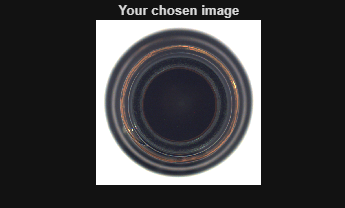

imageChoice = imread(I);

%Run image classification for part type (needed to access pass/fail
% networks)
[partLabel, partConfidence] = classifyImg(imageChoice, InspectionSystem.PartClassifier);

%Run image classification function to return label and confidence score for
% PASS/FAIL
[imgLabel, imgConfidence] = classifyImg(imageChoice, InspectionSystem.ConditionClassifiers.(string(partLabel)));

%Show image along with AI classification results
figure

imshow(imageChoice)
title("Your chosen image")

fprintf("Final Condition Classifier label: %s\n", string(imgLabel));

Final Condition Classifier label: PASS


fprintf("Condition Classifier Confidence score: %.2f%%\n", imgConfidence * 100);

Condition Classifier Confidence score: 100.00%



fprintf("Final Part Classifier label: %s\n", string(partLabel));

Final Part Classifier label: bottle


fprintf("Part Classifier Confidence score: %.2f%%\n", partConfidence * 100);

Part Classifier Confidence score: 100.00%



if lower(string(imgLabel)) == "fail"
    %Run image classification function to return label and confidence score for
    % defect type
    [defectLabel, defectConfidence] = classifyImg(imageChoice, InspectionSystem.DefectTypeClassifiers.(string(partLabel)));
    fprintf("Final Defect Classifier label: %s\n", string(defectLabel));
    fprintf("Defect Classifier Confidence score: %.2f%%\n", defectConfidence * 100);

else
return
end




## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

Your image inspection function (e.g. `inspectPar(I)`) should combine the classical evidence with the AI classification output. 

In other words, your image inspection function should integrate both classical evidence from image processing and an AI classification decision. The AI classifier provides the main decision (PASS/FAIL) while the classical evidence extraction provides interpretability, traceability, and sanity checks for that decision.

Your function should return:

- `finalLabel` (from AI, in Task 3)

- `confidenceScore` (from AI, in Task 3)

- `evidenceOverlay` (from Step 4 in Task 2)

- `evidenceMetrics` (from Step 5 in Task 2)

- (optional) `baselineDecision` and a “disagreement flag” if optional rules in Step 6 from Task 2 and AI output disagree

Optionally, you can also choose to overlay these results on the image using `insertShape(...)` / `insertText(...)`, and save rejects with `imwrite(...)`

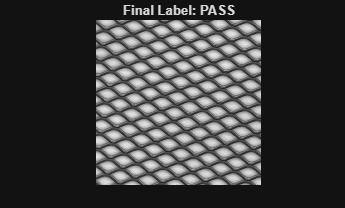


Inspection result:



Final Condition label: PASS


Confidence score: 98.96%


Final Part label: grid


Confidence Score: 100.00%


Final Defect label: NONE


%Below the function, insert a photo to test the entire inspection system
% (make sure that the proper functions are within the same directory as
% this live script)

%DELIVERABLE
function [conditionLabel, conditionConfidenceScore,...
    partLabel, partConfidence, typeLabel, typeConfidence, evidenceOverlay,...
    evidenceMetrics] = inspectPart(I, inspectionStruc)

    
    %Classify part type
    [partLabel, partConfidence] = classifyImg(I, inspectionStruc.PartClassifier);

    %Classify condition (pass/fail)
    [conditionLabel, conditionConfidenceScore] = classifyImg(I, inspectionStruc.ConditionClassifiers.(string(partLabel)));


    %Determine function to run
if lower(string(conditionLabel)) == "fail"

    %Classify defect type
    [typeLabel, typeConfidence] = classifyImg(I, inspectionStruc.DefectTypeClassifiers.(string(partLabel)));

        % Run the matching classical image-processing function.

        switch lower(string(partLabel))

            case "hazelnut"
                [~, evidenceMetrics, ~, ~, evidenceOverlay] = inspectHazelnut(I, typeLabel);

            case "wood"
                [~, evidenceMetrics, ~, ~, evidenceOverlay] = inspectWood(I, typeLabel);

            case "bottle"
                [~, evidenceMetrics, ~, ~, evidenceOverlay] = inspectBottle(I);

            case "grid"
                [evidenceMetrics, evidenceOverlay] = InspectGrid(I, typeLabel);

            otherwise
                error("Unsupported part type: %s", string(partLabel));
        end

else

    % No defect evidence is needed for a passing image.
    typeLabel = categorical("NONE");
    typeConfidence = 1;
    evidenceOverlay = I;

    evidenceMetrics.numComponents = 0;

    evidenceMetrics.maxArea = 0;
    evidenceMetrics.areaRatio = 0;

end
end

%Test function on image for correct output

%Insert image of your choice
I = "D:\EPP 2026 Dataset\mvtec_anomaly_detection_USED_v5\grid\PASS\019.png";
img = imread(I);


[aiConditionLabel, aiConditionScore, aiPartLabel, aiPartConfidence, ... 
    aiTypeLabel, aiTypeConfidence, evidence, metrics] = inspectPart(img,...
    InspectionSystem);

% Display for finalLabel = PASS:
if lower(string(aiConditionLabel)) == "pass"
    % Display the original passing image.
    figure;
    imshow(evidence);

    title(sprintf("Final Label: %s", string(aiConditionLabel)));


CONFUSION MATRIX VERIFICATION
 
----------- PART CLASSIFIER -----------
Class Order:
     bottle 
     grid 
     hazelnut 
     wood 

Confusion Matrix:
    30     0     0     0
     0    43     0     0
     0     0    49     0
     0     0     0    32

 
----------- OVERALL CONDITION CLASSIFIER -----------
Class Order:
     FAIL 
     PASS 

Confusion Matrix:
    26     2
     0   126

 
----------- INDIVIDUAL CONDITION CLASSIFIERS -----------

bottle Condition Classifier
Class Order:
     FAIL 
     PASS 

Confusion Matrix:
     4     0
     0    26


grid Condition Classifier
Class Order:
     FAIL 
     PASS 

Confusion Matrix:
     9     1
     0    33


hazelnut Condition Classifier
Class Order:
     FAIL 
     PASS 

Confusion Matrix:
     8     0
     0    41


wood Condition Classifier
Class Order:
     FAIL 
     PASS 

Confusion Matrix:
     5     1
     0    26

 
----------- OVERALL DEFEC

    fprintf("\nInspection result:\n\n");
    fprintf("Final Condition label: %s\n", string(aiConditionLabel));
    fprintf("Confidence score: %.2f%%\n", aiConditionScore * 100);

    fprintf("Final Part label: %s\n", string(aiPartLabel));
    fprintf("Confidence Score: %.2f%%\n", aiPartConfidence * 100);

    fprintf("Final Defect label: %s\n", string(aiTypeLabel));


% Display for finalLabel = FAIL:
else
    % Display the defect evidence overlay.
    figure;
    imshow(evidence);
    title(sprintf("Final Label: %s", string(aiConditionLabel)));

    % Display results only for failed parts.
    fprintf("Final Condition label: %s\n", string(aiConditionLabel));
    fprintf("Confidence Score: %.2f%%\n", aiConditionScore * 100);
    
    fprintf("Final Part label: %s\n", string(aiPartLabel));
    fprintf("Confidence Score: %.2f%%\n", aiPartConfidence * 100);
    
    fprintf("Final Defect Type label: %s\n", string(aiTypeLabel));
    fprintf("Confidence Score: %.2f%%\n", aiTypeConfidence * 100);
    
    fprintf("Number of suspicious regions: %d\n", metrics.numComponents);
    fprintf("Largest suspicious region: %d pixels\n", metrics.maxArea);
    fprintf("Area ratio: %.4f\n", metrics.areaRatio);
end


## Task 4: Evaluate Inspection System Performance

Now that you've built a hybrid inspection system that integrates classical evidence with an AI decision, your goal in this step is to test the system on a batch of images.

The results of this test should be summarized with a confusion matrix, report yield, and defect rates across the entire batch of images.

Write a script (e.g. `runInspectionSuite.m`) that:

- Splits data into train/test (e.g., `splitEachLabel(...)` or a fixed split)

- Evaluates the trained AI model and trains the inspection system on a test set and logs outcomes

- Produces a confusion matrix with `confusionmat(...)` / `confusionchart(...)`

- Summarizes yield and defect counts in tables and plots

- Visualizes common failure cases (e.g. by creating a montage of common errors using `montage(...)`)

%THIS SECTION IS USED IF THE USER WISHES TO NOT TRAIN THE NETWORK ON THEIR OWN AND
% USE PREVIOUSLY STORED DATA ONLY


% Here, it is recommended to create a separate runInspectionSuite.m file
% (or include as a local helper function) that combines the work you've done 
% so far here and additionally performs the steps outlined in the task description. 
% You can run it from here.

%Load testing set from a previous run of "runInspectionSuiteTRAIN.m" and
% the structure of networks that is associated with it
%{
load testSetoftestingScriptNetworksAndClasses.mat
load testingScriptNetworksAndClasses.mat
%}

run runInspectionSuiteNOTRAIN.m


## Task 5: Test and Evaluate System Robustness

Your goal in this step is to assess how your system performs under simulated variations. You can simulate image inspection station variation by altering the lighting, blur, or noise in the images. Here are some suggested distortions to apply:

- Brightness/contrast: `imadjust(...)`

- Blur: `imgaussfilt(...)`

- Noise: `imnoise(...)`

Then, re-run the evaluation. In other words, run `runInspectionSuite.m `again with the same image set after applying distortions to the images.

Compare how performance changes across conditions by reporting how accuracy and false-reject rates change under simulated variations.

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?